## **Probabilistic roadmap method con Breadth-first search (BFS)**

clear all; clc; close all;

## Set Up Environment

Create a `binaryOccupancyMap` object from a warehouse map. In the warehouse, the mobile robot moves from the loading station to the unloading station to place the goods.

map = load("wareHouseMap.mat").logicalMap;
map = binaryOccupancyMap(map);
gridSize = map.GridSize;  % Restituisce le dimensioni della griglia [numRighe, numColonne]
numRows = gridSize(1);
numCols = gridSize(2);

Visualize the map.

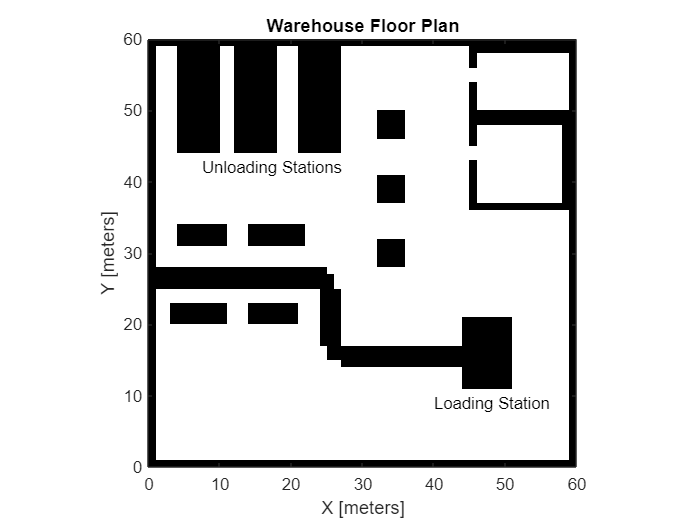

figure
show(map)
title("Warehouse Floor Plan")
% Set the location of text displayed on the map.
loadingStationTextLoc = [40 9 0];
unloadingStationTextLoc = [7.5 42 0];
hold on
text(loadingStationTextLoc(1),loadingStationTextLoc(2),1,"Loading Station");
text(unloadingStationTextLoc(1),unloadingStationTextLoc(2),1,"Unloading Stations");
hold off


% Parametri iniziali
numNodes = 10; % Numero di nodi nel roadmap
startPos = [0, 0]; % Punto iniziale Qs
goalPos = [10, 10]; % Punto finale Qg
xLimits = [0, numRows];
yLimits = [0, numCols];

% Genera nodi casuali
nodes = [startPos; goalPos];
while size(nodes, 1) < numNodes + 2
    newNode = [rand * (xLimits(2) - xLimits(1)) + xLimits(1), rand * (yLimits(2) - yLimits(1)) + yLimits(1)];
    nodes = [nodes; newNode];
end

% Costruzione del grafo
edges = [];
maxDist = 2; % Distanza massima per connettere i nodi
for i = 1:numNodes+2
    for j = i+1:numNodes+2
        if norm(nodes(i,:) - nodes(j,:)) < maxDist
            edges = [edges; i, j]; %#ok<AGROW>
        end
    end
end

% BFS per trovare il percorso dal nodo iniziale al nodo finale
graph = graph(edges(:,1), edges(:,2));

Index in position 2 exceeds array bounds.

path = shortestpath(graph, 1, 2);

% Visualizza il roadmap e il percorso
figure;
hold on;
plot(nodes(:,1), nodes(:,2), 'bo');
plot(nodes(1,1), nodes(1,2), 'go', 'MarkerSize', 10, 'LineWidth', 2); % Punto iniziale
plot(nodes(2,1), nodes(2,2), 'ro', 'MarkerSize', 10, 'LineWidth', 2); % Punto finale
for i = 1:size(edges,1)
    plot([nodes(edges(i,1),1), nodes(edges(i,2),1)], [nodes(edges(i,1),2), nodes(edges(i,2),2)], 'k-');
end
plot(nodes(path,1), nodes(path,2), 'r-', 'LineWidth', 2); % Percorso trovato
title('PRM con BFS');
xlabel('X');
ylabel('Y');
hold off;


% Plot della mappa con i nodi e l'albero PRM
figure;
imshow(map);  % Mostra la mappa
hold on;

% Plot dei nodi generati
scatter(nodes(:,1), nodes(:,2), 50, 'filled', 'g');  % Nodi
scatter(startPoint(1), startPoint(2), 100, 'filled', 'b');  % Punto di partenza
scatter(goalPoint(1), goalPoint(2), 100, 'filled', 'r');  % Punto di arrivo